## Statefeedback example

clc
clear
%transform function of the system
num = [3 4 -2];
den = [1 3 7 5];
%state space representation
[A,B,C,D] = tf2ss(num,den);
sys = ss(A,B,C,D);
poles = eig(A)

poles =   -1.0000 + 2.0000i
  -1.0000 - 2.0000i
  -1.0000 + 0.0000i


%study the controllability
sys_order = order(sys)

sys_order = 3

sys_rank = rank(ctrb(A,B))

sys_rank = 3

Co = ctrb(A,B)

Co =      1    -3     2
     0     1    -3
     0     0     1


R = rank(Co)

R = 3

%eigenvalue placement
p = [-4 -4 -5];
K = acker(A,B,p)

K =     10    49    75


%K = place(A,B,p)
%check the eigenvalues of the colsed loop 
CL_eig = eig(A-B*K)

CL_eig =   -5.0000 + 0.0000i
  -4.0000 + 0.0000i
  -4.0000 - 0.0000i


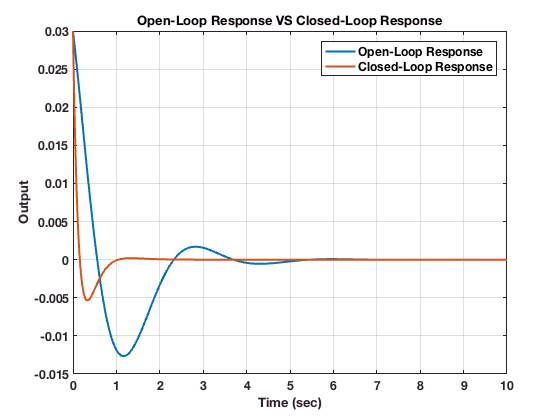

% Open-Loop Response VS Closed-Loop Response to Non-Zero Initial Condition
figure
t = 0:0.01:10;
r = zeros(size(t));
x0 = [0.01 0 0];
[y,t,x] = lsim(sys,r,t,x0);
plot(t,y,'LineWidth',2)
hold on;
sys_cl = ss(A-B*K,B,C,[]);
[y1,t1,x1] = lsim(sys_cl,r,t,x0);
plot(t1,y1,'LineWidth',2)
hold off
title('Open-Loop Response VS Closed-Loop Response')
xlabel('Time (sec)')
ylabel('Output')
grid on;
set(gca,'FontSize',12,'Fontweight','bold')
leg1 = legend('Open-Loop Response','Closed-Loop Response');
set(leg1,'FontSize',12,'Fontweight','bold');